# Computer Assignment #4

## Ali Hamzehpour 810100129

### Part 1

In this part, We want to send a message via a signal. First we convert our string of characters to a binary string then we divide that binary string to smaller segments. Each segment will have a particular signal according to its value. Then we connect these signals together and send them.

For example, We can divide 1010 to 4 1-bit segments and for value 1 we use x = $\sin \left(2\pi t\right)$ signal and for 0 we use x = 0 signal.

#### 1-1

    In this section, We simply define the mapset we use to map each character to a binary string:

map_set = cell(2, 32);

letters = ['a':'z'];
for i = 1:numel(letters)
    binary_string = dec2bin(i-1, 5);
    map_set{1, i} = letters(i);
    map_set{2, i} = binary_string;
end

special_chars = [' ', '!', '.', ',', '"', ';'];
for i = 1:numel(special_chars)
    binary_string = dec2bin(i+25, 5);
    map_set{1, i+26} = special_chars(i);
    map_set{2, i+26} = binary_string;
end

#### 1-2

In this section, We implement a function called *coding_amp* that gets a mapset, a message and rate and encode that message in a signal. The way it's implemented is like what we described earlier. We map the message to a binary string then divide it to smaller segments. The size of a segment is equal to the rate because rate shows how many bits we send in a second. Then we make a signal for that interval according to the value of that segment and add it to our main signal. For example if rate is 2 and our current segment is 10, the signal will be $\frac{2}{3}\sin \left(2\pi t\right)$ for one second.

function x = coding_amp(map_set, msg, rate)
    FS = 100;
    msg_code = '';
    for i = 1 : length(msg)
        char_code = map_set{2, strcmp(map_set(1, :), msg(i))};
        msg_code = [msg_code, char_code];
    end 
    msg_code = [msg_code];
    
    t = 0 : 1 / FS : (length(msg_code) / rate);
    x = zeros(1, length(t));
    sec = 0;
    for i = 1 : rate : length(msg_code)
        if i + rate - 1 > length(msg_code)
            break;
        end
        code = msg_code(i : i + rate - 1);
        code = bin2dec(code);
        coeff = code / (2 ^ rate - 1);
        start_index = sec * FS + 1;
        end_index = start_index + FS;        
        x(start_index : end_index) = coeff * sin(2 * pi * t(start_index : end_index));
        sec = sec + 1;
    end
end

#### 1-3

In this section we test our function with message "signal" and with rate = 1, 2, 3:

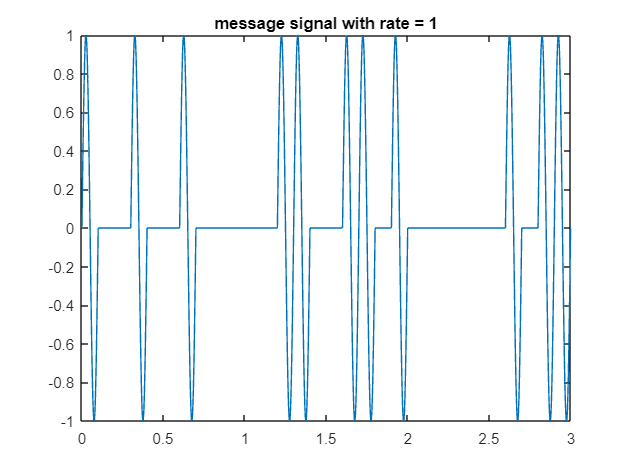

figure;
x1 = coding_amp(map_set, 'signal', 1);
t1 = 0:1/FS:(length(x1)-1)/FS;
plot(t1, x1);
title('message signal with rate = 1');

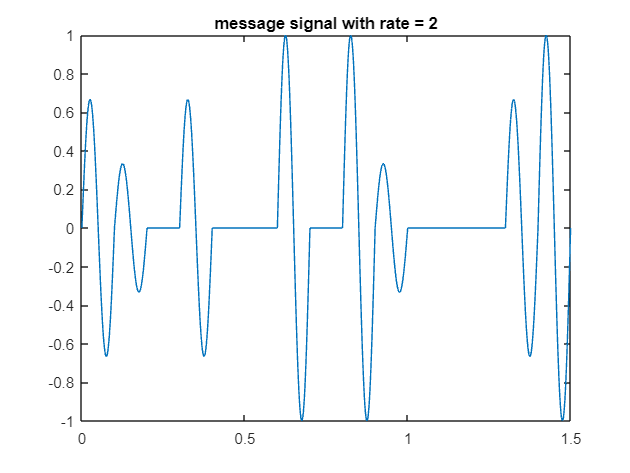

figure;
x2 = coding_amp(map_set, 'signal', 2);
t2 = 0:1/FS:(length(x2)-1)/FS;
plot(t2, x2);
title('message signal with rate = 2');

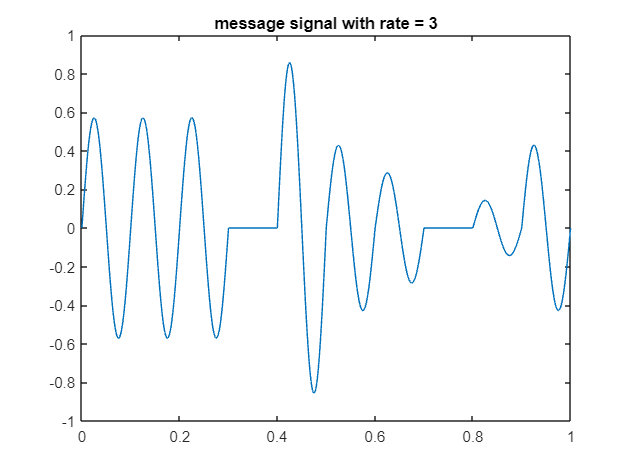

figure;
x3 = coding_amp(map_set, 'signal', 3);
t3 = 0:1/FS:(length(x3)-1)/FS;
plot(t3, x3);
title('message signal with rate = 3');

#### 1-4

In this section, We implement a function called *decoding_amp *that gets a mapset, a signal and a rate then decodes the message that is hidden in the signal. The main idea is to use correlation to determine that our current segment of signal is more similiar to which of the signals we made for each binary segment. Correlation here is simply the dot product of the signal with $2\sin \left(2\pi t\right)$ and in theory is the integral of two signals:

#### 
$$\mathrm{corr}=\int \mathrm{signal}\left(t\right)\ldotp 2\sin \left(2\pi t\right)\mathrm{dt}$$
 

In discrete world:

#### 
$$\mathrm{corr}=\sum_k \mathrm{signal}\left(k\right)\ldotp 2\sin \left(2\pi k\right)$$


We also use a dynamic threshold so if our signal has noise and it doesn't match the optimal correlation we still can determine the binary string.

function msg = decoding_amp(map_set, coded_msg, rate);
   FS = 100;
   sec = 0;
   t = 0 : 1/FS : (length(coded_msg)-1)/FS;
   binary_msg = '';
   msg = '';
   for i = 1 : FS : length(coded_msg) - 1
        start_index = sec * FS + 1;
        end_index = start_index + FS;  
        slice = coded_msg(start_index : end_index);
        signal = zeros(1, length(coded_msg));
        signal = 2 * sin(2 * pi * t(start_index : end_index));
        correlation = 0.01 * dot(signal, slice);
        for coeff = 0 : 2 ^ rate - 1
            if abs(correlation - (coeff / (2 ^ rate - 1))) <= 1 / (2 * (2 ^ rate - 1))
                bin_coeff = dec2bin(coeff);
                extended = strcat(repmat('0', 1, rate - numel(bin_coeff)), bin_coeff);
                binary_msg = [binary_msg, extended];
                break;
            end
        end 
        sec = sec + 1;
   end 
   for i = 1 : 5 : length(binary_msg) - 4
        msg = [msg, map_set{1, strcmp(map_set(2, :), binary_msg(i : i + 4))}];
   end
end

To test our function, We give it the signals we made in the previous part:

msg1 = decoding_amp(map_set, x1, 1);
fprintf('message with rate = 1: %s\n', msg1);

message with rate = 1: signal


msg2 = decoding_amp(map_set, x2, 2);
fprintf('message with rate = 2: %s\n', msg2);

message with rate = 2: signal


msg3 = decoding_amp(map_set, x3, 3);
fprintf('message with rate = 3: %s\n', msg3);

message with rate = 3: signal


#### 1-5

In order to add noise to our signals, we use *randn *function which generates a gaussian noise with mean = 0 and variance = 1:

normal = randn(1, 3001);
var_normal = var(normal);
mean_normal = mean(normal);
fprintf("variance: %f, mean: %f", var_normal, mean_normal);

variance: 0.994273, mean: -0.000886

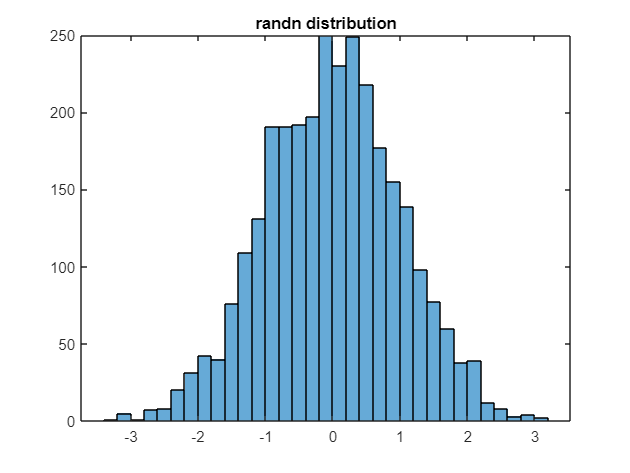

figure;
histogram(normal);
title('randn distribution');

#### 1-6

We add a noise with std = 0.01 to our signals and decode them. As you can see all of the results are correct.

std = 0.01;
x1_noise = x1 + std * normal;
x2_noise = x2 + std * normal(1 : length(x2));
x3_noise = x3 + std * normal(1 : length(x3));
msg1 = decoding_amp(map_set, x1_noise, 1);
fprintf('message with rate = 1: %s\n', msg1);

message with rate = 1: signal


msg2 = decoding_amp(map_set, x2_noise, 2);
fprintf('message with rate = 2: %s\n', msg2);

message with rate = 2: signal


msg3 = decoding_amp(map_set, x3_noise, 3);
fprintf('message with rate = 3: %s\n', msg3);

message with rate = 3: signal


#### 1-7,8

In this section we slowly increase std to see how our decoding works with different rates. As you can see decoding with lower rate is more tolerant against noise because the difference of ideal correlations between different signals are more.

We increased std until 1 and decoding with rate = 1 was tolerant to all of them.

max_noise = zeros(1, 3);
for std = 0.01 : 0.01 : 1
    x1_noise = x1 + std * normal;
    x2_noise = x2 + std * normal(1 : length(x2));
    x3_noise = x3 + std * normal(1 : length(x3));
    msg1 = decoding_amp(map_set, x1_noise, 1);
    msg2 = decoding_amp(map_set, x2_noise, 2);
    msg3 = decoding_amp(map_set, x3_noise, 3);
    if (strcmp(msg1, 'signal'))
        max_noise(1) = std;
    end
    if (strcmp(msg2, 'signal'))
        max_noise(2) = std;
    end
    if (strcmp(msg3, 'signal'))
        max_noise(3) = std;
    end
end
fprintf('max noise for rate = 1: %f\n', max_noise(1));

max noise for rate = 1: 1.000000


fprintf('max noise for rate = 2: %f\n', max_noise(2));

max noise for rate = 2: 0.680000


fprintf('max noise for rate = 3: %f\n', max_noise(3));

max noise for rate = 3: 0.360000


#### 1-9

***How could we make our decoding more tolerant to noises without decreasing bit rate?***

If our sender had more power to send signals with larger domains, we would have larger thresholds between our ideal correlation so our decoding would be more tolerant to the noise.

#### 1-10

***How much can we increase the bit rate if we don't have noise?***

If we don't have noise, we can assume that the whole data is one segment and send the it all in one second if the message is not too long. If the message is too long, we may not be able to calculate the values for each signal because we'll have large exponents. So our bit rate will be: 


$$\max \left(\mathrm{computer}\;\mathrm{limit},\;\;\left(\mathrm{length}\left(\mathrm{messgae}\right)*5\right)\;\frac{\mathrm{bit}}{\sec }\right.$$


because each charcter is mapped to 5 bits and if we send all data in one second we'll have such bit rate.

#### 1-11

***Will our decoding be more tolerant to noise if we use ***$10\;\sin \left(2\pi t\right)$*** instead of ***$2\;\sin \left(2\pi t\right)$*** in our correlation?***

No. Because in this situation the noise effect will be stronger in calculating correlation too so the overall result won't be different. But if we increase the domain of our main signals, Only their effect will be stronger and noise will have less effect(section 1-9)

#### 1-12

***Comparsion between ADSL speed and our signals***

home ADSL speed is in order of ${10}^{6\;} \frac{\mathrm{bits}}{\sec }$ while our signals were in order of $1\;\frac{\mathrm{bits}}{\sec }$ !

### Part 2

In this part we want to use convolution for calculating correlation to estimate the distance of a car that we send a signal towards and recieve its reflection.

#### 2-1

In this part we simply plot the sent signal and recieved signal:

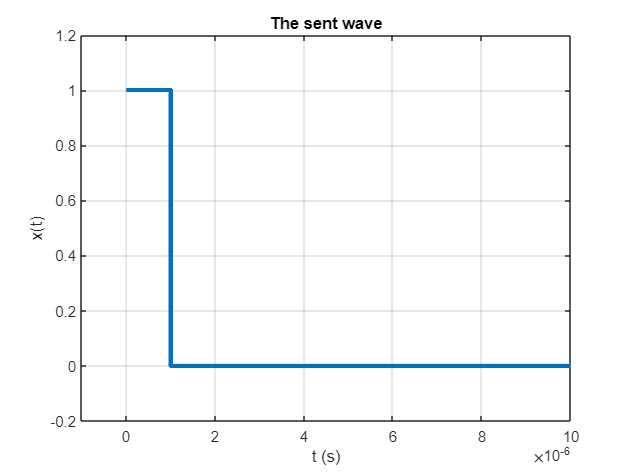

ts = 1e-9;
T = 1e-5;
tau = 1e-6;

t = 0:ts:T;
x_sent = zeros(size(t));
N = round(tau / ts);
x_sent(1:N) = 1;
figure;
plot(t, x_sent, 'LineWidth', 3);
title("The sent wave")
ylabel("x(t)")
xlabel("t (s)")
ylim([-0.2 1.2]);
xlim([-10^-6 10^-5]);
grid on

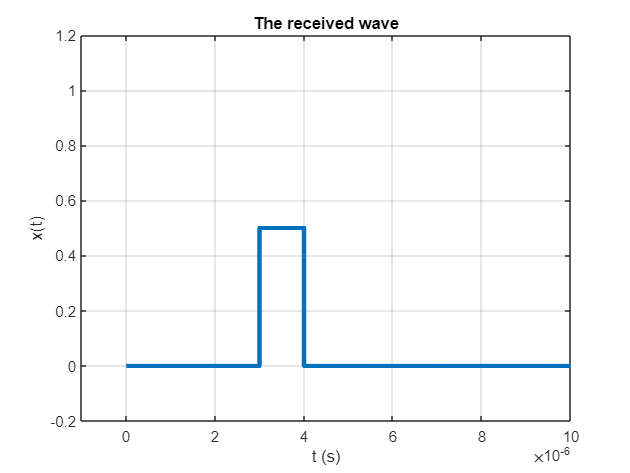

figure;
alpha = 0.5;
R = 450;
C = 3e8;
td = 2 * R / C;
td_index = round(td / ts);
x_received = zeros(size(t));
x_received(td_index : td_index + N) = alpha;
plot(t, x_received, 'LineWidth', 3);
title("The received wave")
ylabel("x(t)")
xlabel("t (s)")
ylim([-0.2 1.2]);
xlim([-10^-6 10^-5]);
grid on

#### 2-2

Now we calculate the convolution of the sent signal and recieved signal. The maximum happens when these two signal are on each other. We know that in convolution we reverse and shift the signal. we need to reverse the recieved signal and shift it $\tau +t_d$ times in order to reach maximum. So after calculating the convolution we find the maximum point the reduce it by $\tau$ to find $t_d$. Now that we have $t_d$ we can calculate the distance.

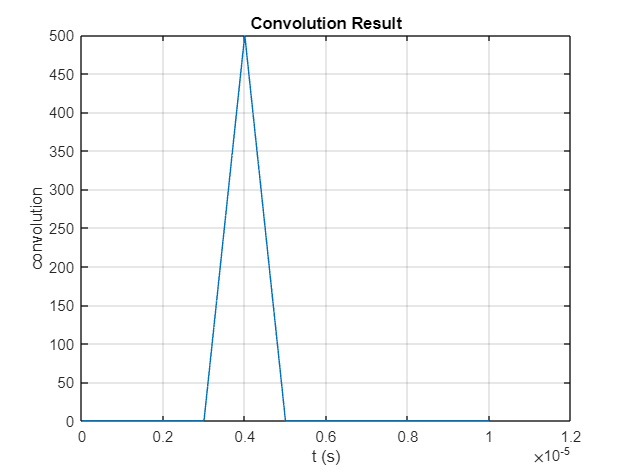

figure;
correlation = conv(x_received, x_sent);
plot(t, correlation(1 : length(t)));
title("Convolution Result")
ylabel("convolution")
xlabel("t (s)")
grid on

[mx_cor, td_derived] = max(correlation);
td_derived = td_derived * ts - tau;
R_derived = C * td_derived / 2;
fprintf("distance is %f\n", R_derived);

distance is 449.850000


#### 2-3

In this part we add noise to the signal and increase it to see how error in this method grows. As we see our method fails to work(has error > 10m) when noise power is bigger than 2.5.

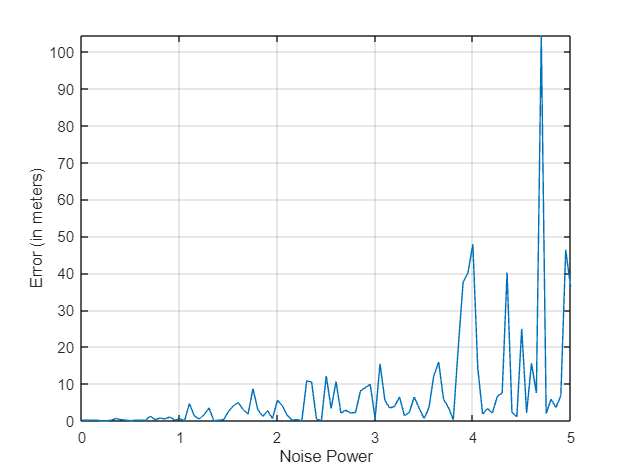

figure;
noise_power = 0:0.05:5;
errors = zeros(size(noise_power));
tlen = length(t);
for i = 1 : length(noise_power)
    cur_noise_power = noise_power(i);
    cur_noise = cur_noise_power * randn(1, tlen);
    x_recieved_noise = x_received + cur_noise;
    cor = conv(x_sent, x_recieved_noise);
    [mx_cor, td_derived] = max(cor);
    td_derived = td_derived * ts - tau;
    R_derived = C * td_derived / 2;
    err = abs(R_derived - R);
    errors(i) = err;
end
plot(noise_power, errors)
xlabel("Noise Power")
ylabel("Error (in meters)")
ylim([0, max(errors)])
grid on

### Part 3

In this part we play some sounds one after other to make a number calling system.

First we make the mapset which map each number and word to a voice:

nums = {};
for i = 1 : 9
    nums{1, size(nums, 2) + 1} = num2str(i);
end
for i = 10 : 20
    nums{1, size(nums, 2) + 1} = num2str(i);
end
for i = 20 : 10 : 90
    nums{1, size(nums, 2) + 1} = num2str(i);
end
voice_names = {'baje', 'o', 'shomare'};
voice_names = [voice_names, nums];
map_set = containers.Map;

for i = 1:numel(voice_names)
    audioFileName = strcat(voice_names(i), '.ogg');
    audioFilePath = fullfile('./bank-voice', audioFileName);
    [audioData, fs] = audioread(audioFilePath{1, 1});
    map_set(voice_names{i}) = audioData;
end

save('map_set_data.mat', 'map_set');

Then we implement a function called *calling_customer *which gets a customer number and a bajeh number and says:

#### شماره ی ... به  باجه  ی

function calling_customer(customer_num, baje_num)
    if (customer_num >= 100 || customer_num <= 0 || baje_num >= 10 || baje_num <= 0)
        error('customer number must be between 1 and 99, baje number must be between 1 and 9');
    end
    load('map_set_data.mat');
    FS = 48000;
    sound(map_set('shomare'), FS);
    pause(2);
    
    if (customer_num > 20 && mod(customer_num, 10) ~= 0)
        sound(map_set(num2str(floor(customer_num / 10) * 10)), FS);
        pause(0.5);
        sound(map_set('o'), FS);
        pause(0.6);
        sound(map_set(num2str(mod(customer_num, 10))), FS);
    else
        sound(map_set(num2str(customer_num)), FS);
    end
       pause(1); 
    sound(map_set('baje'), FS);
    pause(2);
    sound(map_set(num2str(baje_num)), FS);
end

Now we test it:

calling_customer(36, 4); 

### Part 4

In this part we have a dataset which contains information about some people's health and whether they have diabetes or not. We use MATLAB's machine learning tools to learn this dataset and predict new samples.

### 4-1

The result with SVM model that has all features:

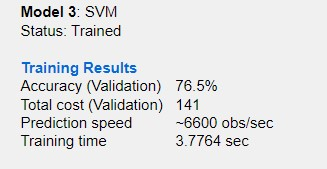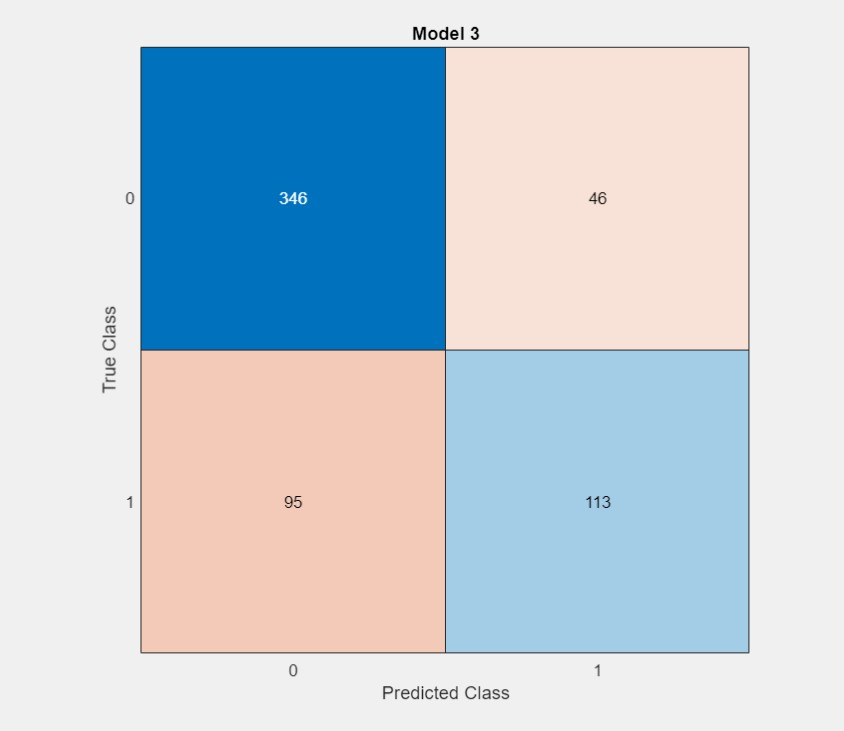

### 4-2

Now we train models which only use one feature to predict:

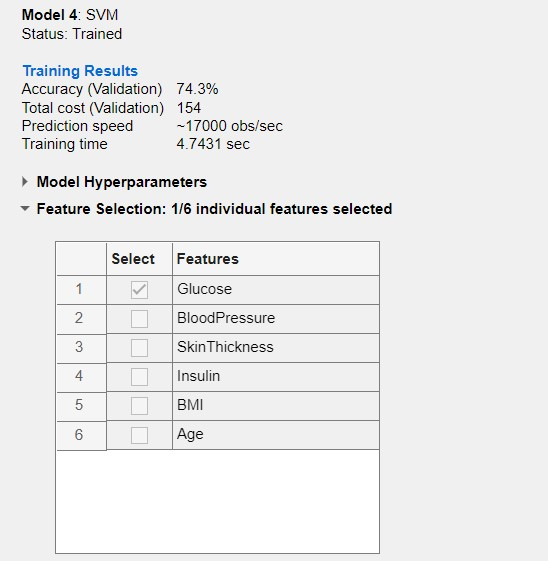

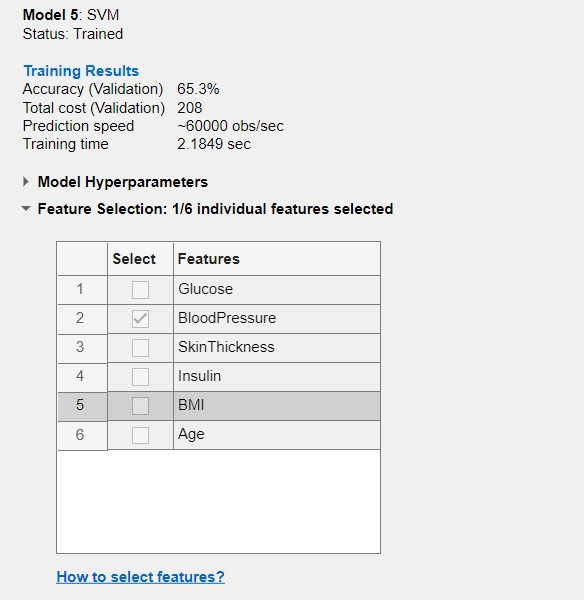

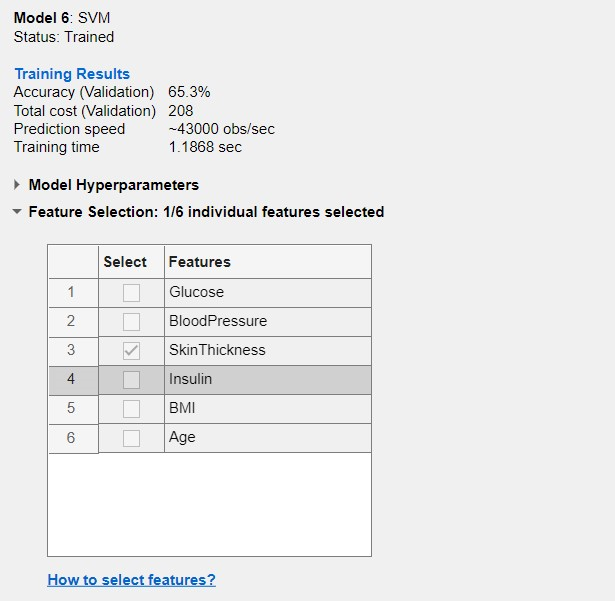

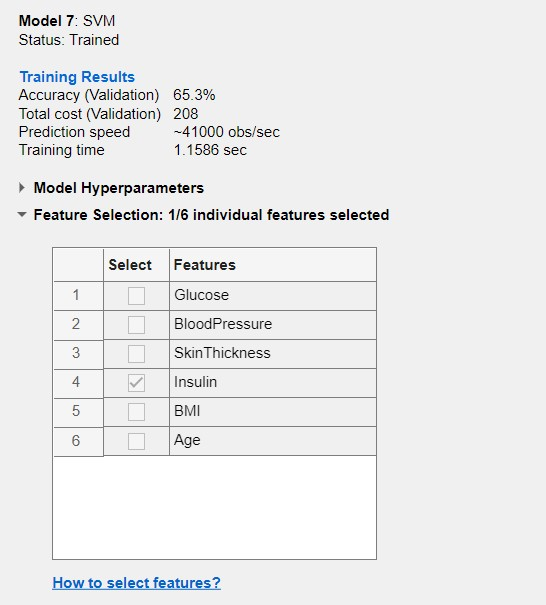

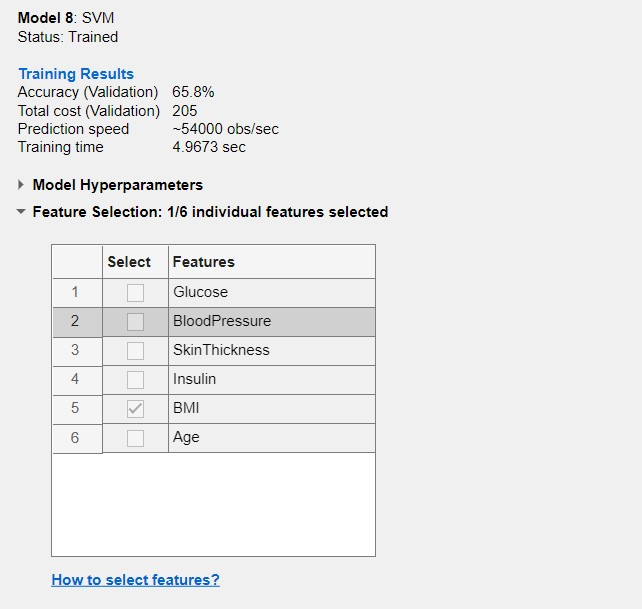

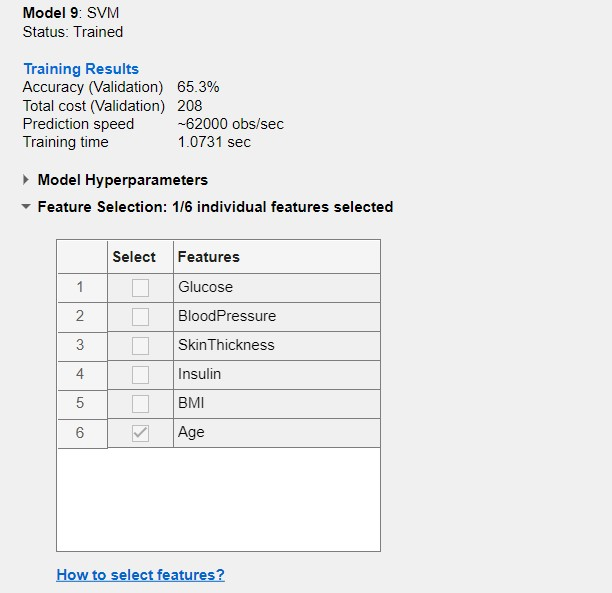

As you can see most of the features don't give us many information alone but Glucose itself is a good measure for prediction.

### 4-3,4

finally we export our model in section 4-1 and use it to predict train samples and test samples:

train_prediction = trainedModel.predictFcn(diabetestraining);
train_accuracy = mean(table2array(diabetestraining(:, 'label')) == train_prediction);
fprintf('Training accuracy: %f\n', train_accuracy);

Training accuracy: 0.775000



test_data = readtable('diabetes-validation.csv');
test_prediction = trainedModel.predictFcn(test_data);
test_accuracy = mean(table2array(test_data(:, 'label')) == test_prediction);
fprintf('Test accuracy: %f\n', test_accuracy);

Test accuracy: 0.780000


###     ‏‏